s = rng(11);            % Set RNG state for repeatability

% Simulation parameters
numSym = 6000;          % Number of OFDM symbols to modulate
osf = 8;                % Oversampling factor

% OFDM parameters
N = 256;                % FFT length
cpLen = 16;             % Cyclic prefix length
modOrder = 4;           % QAM modulation order

% SC-FDMA parameters
M = 50;                 % Number of subcarriers
L = 1;                  % Subcarrier mapping interval (L=1 for localized)

% Create a random stream of bits, encode them in the desired baseband
% modulation, and map onto an OFDM grid
bitsPerSubcarrier = log2(modOrder);
dataIn = randi([0 1],bitsPerSubcarrier*M, numSym);      % Create a random data stream
ofdmDataGrid = qammod(dataIn,modOrder, ...              % Map the bits into the complex domain                        
        InputType='bit', ...
        UnitAveragePower=true);           
ofdmDataGrid = cat(1,ofdmDataGrid,zeros(N-M,numSym));   % Zero-pad the unused subcarriers

% Take the same data used for OFDM, perform the DFT to precode the
% data, and form an SC-FDMA grid
scfdmaData = fft(ofdmDataGrid(1:M,:),M);                % Precode the data in the M subcarriers

% Map the precoded data via localized (L=1) or distributed (other L) mapping
scfdmaDataGrid = zeros(N,numSym);
scfdmaDataGrid(1:L:M*L,:) = scfdmaData

scfdmaDataGrid =   -2.8284 - 2.8284i   1.4142 - 1.4142i   0.0000 + 5.6569i   5.6569 - 0.0000i   2.8284 + 7.0711i -11.3137 + 1.4142i  -2.8284 + 1.4142i   5.6569 - 8.4853i   5.6569 + 4.2426i  -4.2426 + 1.4142i   2.8284 - 1.4142i  -5.6569 + 1.4142i   1.4142 + 1.4142i  -5.6569 - 4.2426i   2.8284 + 8.4853i   2.8284 + 9.8995i  -4.2426 - 4.2426i   2.8284 - 8.4853i   1.4142 + 0.0000i   9.8995 + 4.2426i   4.2426 + 7.0711i   4.2426 -15.5563i  -2.8284 - 2.8284i  -4.2426 - 1.4142i  -2.8284 - 5.6569i  -7.0711 - 5.6569i  -7.0711 - 4.2426i   1.4142 + 0.0000i  -0.0000 - 1.4142i   1.4142 - 4.2426i   0.0000 - 0.0000i  -1.4142 +11.3137i   2.8284 - 2.8284i  -5.6569 + 4.2426i   4.2426 + 7.0711i  -2.8284 - 2.8284i   1.4142 - 1.4142i   0.0000 +11.3137i  -4.2426 - 5.6569i   4.2426 - 8.4853i   2.8284 - 5.6569i   0.0000 - 1.4142i  -2.8284 - 4.2426i   4.2426 + 4.2426i   8.4853 + 2.8284i   8.4853 + 8.4853i  -2.8284 + 8.4853i   2.8284 - 5.6569i  -8.4853 - 4.2426i  -2.8284 + 9.8995i
   0.0532 + 1.8472i  -6.0318 - 3

% Modulate with OFDM
xOFDM    = ofdmmod(ofdmDataGrid,N,cpLen,OversamplingFactor=osf);
xSCFDMA  = ofdmmod(scfdmaDataGrid,N,cpLen,OversamplingFactor=osf);

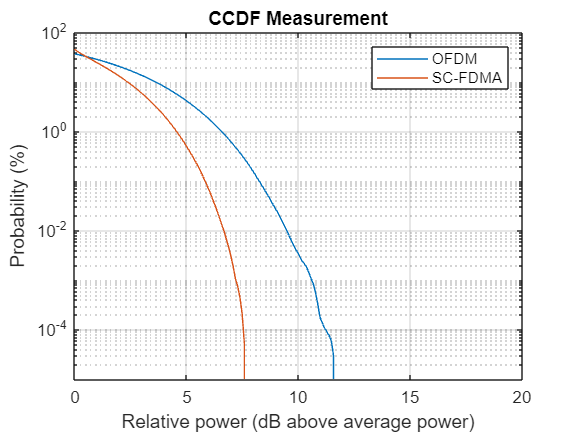

% Normalize the signal powers so that the average power is the same for
% both signals when comparing PAPR
pwrOFDM = sum(abs(xOFDM))/length(xOFDM);
pwrSCFDMA = sum(abs(xSCFDMA))/length(xSCFDMA);
    
% Compute and plot the CCDF
pm = powermeter(ComputeCCDF=true,Measurement="Peak-to-average power ratio");
paprs = pm([xOFDM/pwrOFDM xSCFDMA/pwrSCFDMA]);

plotCCDF(pm);
legend('OFDM','SC-FDMA');

disp(['The PAPR for OFDM is ' num2str(paprs(1)) ' dB']);

The PAPR for OFDM is 11.595 dB


disp(['The PAPR for SC-FDMA is ' num2str(paprs(2)) ' dB']);

The PAPR for SC-FDMA is 7.6481 dB


disp(['The improvement in PAPR from OFDM to SC-FDMA is ' num2str(paprs(1)-paprs(2)) ' dB']);

The improvement in PAPR from OFDM to SC-FDMA is 3.9468 dB


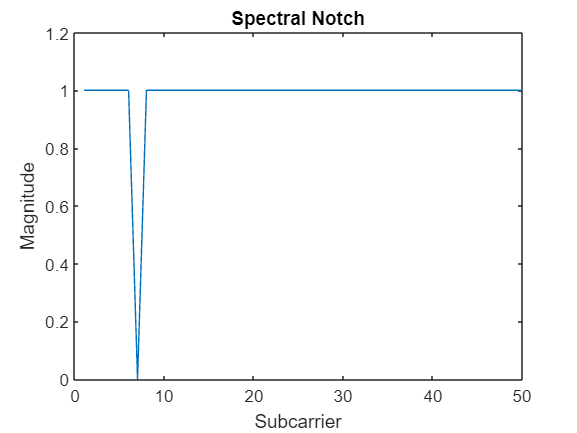

% Demodulate using OFDM
yOFDM   = ofdmdemod(xOFDM,N,cpLen,OversamplingFactor=osf);
ySCFDMA = ofdmdemod(xSCFDMA,N,cpLen,OversamplingFactor=osf);

% Simulate a notch in the spectrum by nulling the 5th subcarrier
yOFDM(7,:)       = 0;
ySCFDMA(10*L+1,:) = 0;
figure;
plot(abs(yOFDM));
xlim([0 M]);
title('Spectral Notch');
xlabel('Subcarrier');
ylabel('Magnitude');

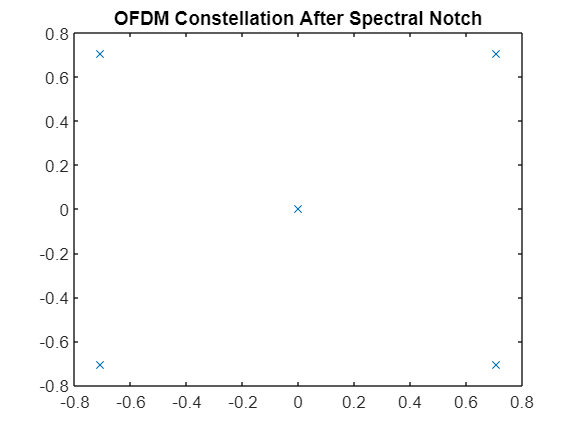

figure;
plot(yOFDM(:),'x');
title('OFDM Constellation After Spectral Notch');

% Despread the SC-FDMA subcarriers
sSCFDMA = ifft(ySCFDMA(1:L:M*L,:),M);

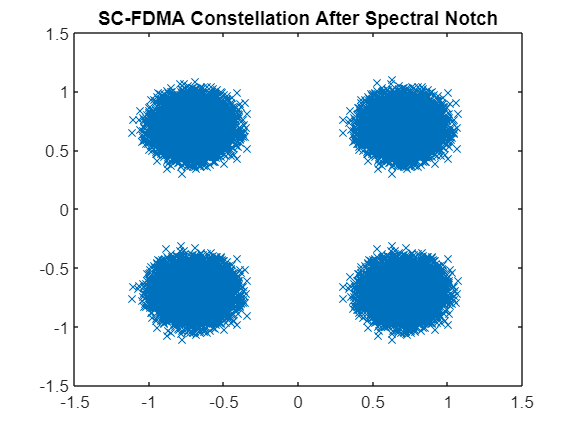

figure;
plot(sSCFDMA(:),'x');
title('SC-FDMA Constellation After Spectral Notch');

% Hard decision decoding
decOFDM   = qamdemod(yOFDM(1:M,:), modOrder, OutputType='bit',UnitAveragePower=true);
decSCFDMA = qamdemod(sSCFDMA, modOrder, OutputType='bit',UnitAveragePower=true);

% BER of notched signal
BER = comm.ErrorRate(ResetInputPort=true);
berOFDM   = BER(dataIn(:),decOFDM(:),true);
berSCFDMA = BER(dataIn(:),decSCFDMA(:),true);

disp(['BER for OFDM with spectral null = ' num2str(berOFDM(1))]);

BER for OFDM with spectral null = 0.010017


disp(['BER for SC-FDMA with spectral null = ' num2str(berSCFDMA(1))]);

BER for SC-FDMA with spectral null = 0
